# **PREDICCIÓN CON MLP**

En este programa se va a prececir la evolución de un serie temporal mediante una red neuronal MLP. Se simulará mediante las instrucciones específicas de definición de una red "Feedforward".

Se dispondrá de cuatro series temporales: el precio de los derechos de emisión de CO2, el consumo de energía eléctrica en la EII, el precio del barril de petroleo Brent y el precio del gas natural.

En primer lugar se cierran todas las ventanas abiertas y se limpian todas las varibles.

close all
clear all

## **CARGA DE LOS DATOS  **

Los datos están guardados en columnas en las series temporales, por lo que deben ser pasados a formato filas, que es como Matlab requiere que sean suministrados a las instrucciones de simulacion del MLP.

%serie0=readmatrix('Derechos_CO2.xlsx','Range','B2:B4555');  % numdatos=15; numneuronas= [40 30 20 10]; ultimdatos=300; porcenEntVal=0.7; epochs=400;
%serie0=xlsread('consumos_eii_2022.xlsx','L3:L8762');
%serie0=readmatrix('Petroleo_Brent.xlsx','Range','B1:B9609');
%serie0=readmatrix('Gas_Natural.xlsx','Range','B4:B7097');
serie=serie0';

plot(serie,'k')
title('Serie temporal')

## **DEFINICIÓN DE LA RED NEURONAL**

**DATOS AJUSTABLES**

Para determinar la estructura de la red es necesario proporcionar el **número de datos anteriores que se presentan a la red** (*numdatos*), el **número de neuronas de la capa MLP** (*n*`umneuronas`) y la **distribución** de los datos entre  **entrenamiento y validación**, expresado en tanto por uno de entrenamiento. Se ajusta también el **número de los últimos datos predichos que se desea representar gráficamente** (*ultimdatos*). Esto se hace para tener una visión gráfica más detallada de la precisión de las predicciones, ya que la representación de todos los datos puede ser poco infomativa debido a su gran número.

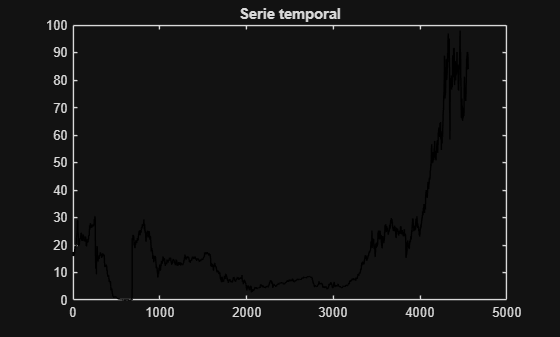

numdatos=15;
numneuronas= [40 30 20 10];

ultimdatos=300;
porcenEntVal=0.7;

**ESTRUCTURA DE LA RED**

La definción de la estructura de una red neuronal MLP se hace mediante la instrucción '*feedforwardnet*' (consultar su funcionamiento en la ayuda). Es necesario especificar el algoritmo de entrenamiento, en este caso el de Levemberg-Marquard (*'trainlm*'). Este algoritmo no permite la división en lotes de los datos de entrenamiento, cada iteración del algoritmo procesa todos los datos del conjunto de entrenamiento. Será necesario también proporcionar el número de neuronas que tendrá la capa oculta (*numneuronas*). Si se quisieran definir más de una capa oculta se proporcionaría un vector fila con el número de neuronas en cada capa.

No es necesario especificar ni el número de entradas ni el de salidas ya que esa informaciónse se obtiene automáticamante de los datos que se presentan al realizar en entrenamiento.

redPredic=feedforwardnet(numneuronas,'trainlm');

Los diferentes hiperparámetros que se pueden ajustar para definir la estructura y funcionamiento de la red MLP se pueden consultar en las direcciones:

[https://es.mathworks.com/help/releases/R2025b/deeplearning/ug/neural-network-object-properties.html](https://es.mathworks.com/help/releases/R2025b/deeplearning/ug/neural-network-object-properties.html)

[https://es.mathworks.com/help/releases/R2025b/deeplearning/ug/neural-network-subobject-properties.html](https://es.mathworks.com/help/releases/R2025b/deeplearning/ug/neural-network-subobject-properties.html)

Todos los hiperparámetros están organizados en una *structure*. El primer campo de cada clase es el nombre que se le ha dado a la red neuronal que se va a utiizar (en este caso *'redPredic'*). 

Sólamente se se ajustan algunos hiperpárametros, el resto se deja en sus valores por defecto. Los ajustado son:

- Funciones de activación neuronal: tangente hiperbólica (*tansig*) para la capa de entrada  y lineal (*purelin*) para la de salida.

- División de datos. Matlab permite dividir los datos en conjuntos de entrenamiento, validación y test. Esta tarea la hacemos nosotros para controlar mejor la organización de los datos. Para ello el hiperparámetro  que controla esta división se fija al valor *none*. De esta forma Matlab interpreta que todos los datos serán para entrenamiento.

- Matlab exije que los datos de entrada estén nomalizados. En este caso se ha elegido la opción de restar a cada dato la media y dividir por la desviación estándar (*mapstd*).

- Ajustar el número de pasos de entrenamieno, es decir el número de veces que se repetirá el proceso de entrenamieto (*epochs*). Para ajustar este hiperparámetro consultar la instrucción *'trainlm'*.

- No presentar la pantalla de seguimiento del entrenamiento.

redPredic.layers{1}.transferFcn='tansig';
redPredic.layers{2}.transferFcn='purelin';
redPredic.divideFcn='dividetrain';
redPredic.divideMode='none';
redPredic.inputs{1}.processFcns={'mapstd'};
redPredic.outputs{2}.processFcns={'mapstd'};
redPredic.trainParam.epochs=400;
redPredic.trainParam.showWindow=false;

Se fija la semilla del generador de numeros aleatorios para que siempre se genere la misma secuencia aleatoria de inicio del entrenamiento.

rng(1);

## ENTRENAMIENTO Y PREDICCIÓN DE LA SERIE

Índice que señala al último dato de la serie de entrenamiento.

longEntre=ceil(porcenEntVal*length(serie));

Serie con los datos reales que se utilizarán para validar los modelos:

serieVal=serie(longEntre+1:length(serie));

**DATOS DE ENTRENAMIENTO**

Se forman los vectores de entrenamiento: datos de entrada y valor esperado de la salida.

for k=1:1:longEntre-numdatos
    patronEntr(:,k)=serie(k:k+numdatos-1);
    patronSal(:,k)=serie(k+numdatos);
end

**DATOS DE VALIDACIÓN**

Se forman los vectores de entrada que se utilizaran para validar la capacidad de predicción de la red neuronal.

for k=longEntre:1:length(serie)-1
    patronPred(:,k-longEntre+1)=serie(k-numdatos+1:k);
end

**ENTRENAMIENTO Y PREDICCIÓN**

Solo a título informativo, se activa un reloj interno para saber el tiempo que lleva todo el proceso de simulación de la red neuronal.

tic

redPredic=train(redPredic,patronEntr,patronSal);
predicciones=sim(redPredic,patronPred);

toc

## **PRESENTACIÓN DE LOS RESULTADOS**

**PRESENTACIÓN GRÁFICA DE LOS RESULTADOS**

Se generarán tres gráficas: compartiva de todos los datos predichos con sus valores reales, comparativa de los últimos datos predichos con su valores reales y errores cometidos en las predicciones.

plot(serie(longEntre+1:length(serie)),'k')
hold on
plot(predicciones,'r')
title('PREDICCIONES.   Negro: reales \color{red}Rojo: predichas')
hold off
plot(serie(length(serie)-ultimdatos:length(serie)),'k')
hold on
plot(predicciones(length(predicciones)-ultimdatos:length(predicciones)),'r')
title([num2str(ultimdatos),' ÚLTIMAS PREDICTIONES. Negro:reales \color{red}Rojo:predichas'])
hold off
error=serieVal-predicciones;

Elapsed time is 238.062984 seconds.



plot(error,'k')
title('ERRORES DE TODAS LAS PREDICCONES')

**TABLA DE ERRORES**

Cálculo de todas las métricas de error que miden las prestaciones del modelo.

prestaciones=calculoErr(serieVal,error);

Se organizan los datos para presentarlos en una tabla.

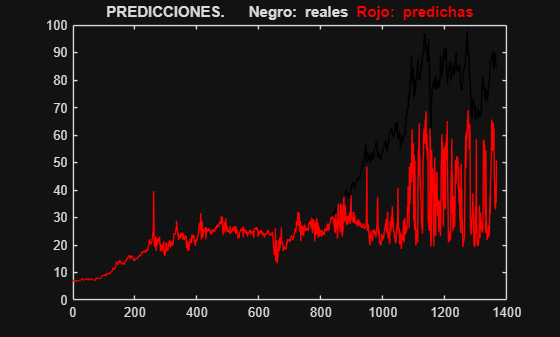

prestaciones=round(prestaciones,4);
MAPE=prestaciones(1);
MAE=prestaciones(2);
MSE=prestaciones(3);

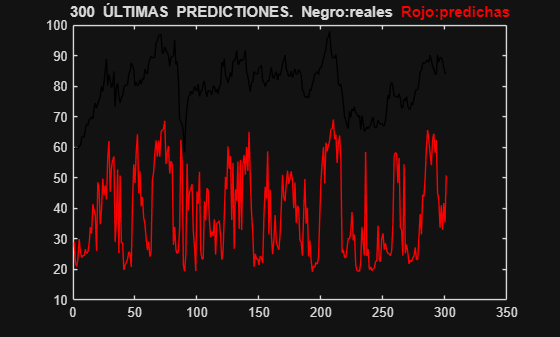

RMSE=prestaciones(4);
R2=prestaciones(5);
MeanErr=prestaciones(6);
Std=prestaciones(7);


errores=table(MAPE,MAE,MSE,RMSE,R2,MeanErr,Std)

## **FUNCION PARA CALCULAR LOS ÍNDICES DE ERROR**

Función que calcula los índices de error de las predicciones: MAPE, MAE, MSE, RMSE, R2, error medio y desviación estándar.

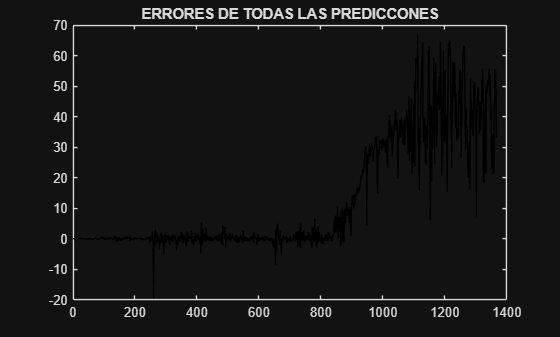

function [indice]=calculoErr(reales,errorAbs)
indice(1)=mean(abs(errorAbs./reales))*100                        %MAPE

indice(2)=mean(abs(errorAbs))                                    %MAE
indice(3)=mean(errorAbs.^2)                                      %MSE
indice(4)=sqrt(indice(3))                                        %RMSE

indice = 20.6755

indice =    20.6755   13.2361


indice =    20.6755   13.2361  513.7988


indice =    20.6755   13.2361  513.7988   22.6671


indice =    20.6755   13.2361  513.7988   22.6671    0.2177


indice =    20.6755   13.2361  513.7988   22.6671    0.2177   12.7940


indice =    20.6755   13.2361  513.7988   22.6671    0.2177   12.7940   18.7181


indice(5)=1-sum(errorAbs.^2)./sum((reales-mean(reales)).^2)      %R2
indice(6)=mean(errorAbs)                                         %ERROR MEDIO
indice(7)=std(errorAbs)                                          %DESVIACIÓN ESTANDAR
end

errores = 1×7 table
     MAPE      MAE       MSE      RMSE       R2      MeanErr     Std  
    ______    ______    _____    ______    ______    _______    ______

    20.675    13.236    513.8    22.667    0.2177    12.794     18.718
